%Student Dave's particle filter tutorial

%In this tutorial, The Frequentisian Ninja Clan has just run into the mysterious Quail.
%The Quail was just doing it's typical magical quail stuff throughout the forest like, I
%dunno, freeing catapillars from evil monkey spells.
%The ninja clan, knowing the impossible agility of the Quail, began to
%stretch out and prepare for attack.  During which the Quail mediated and
%generated a highly non-linear flight model with strong illusions (i.e. weird measurements :P) and takes off!
%
%The student ninja's make chase but, only knowing linear algorithms, they
%fail very quickly.  However, the Master Frequentisian Ninja knows the
%particle filter, and after a cognitively and physical exhaustive, epic
%chase, the Master catches the Quail, and takes it back to their secret
%Dojo.

%Here, we learn this master skill, known as the particle filter, as applied
%to a highly nonlinear model. :)!

%Adapted from Dan Simon Optimal state estimation book and Gordon, Salmond,
%and Smith paper.

## clear everything

clear all
close all
clc

## initialize the variables

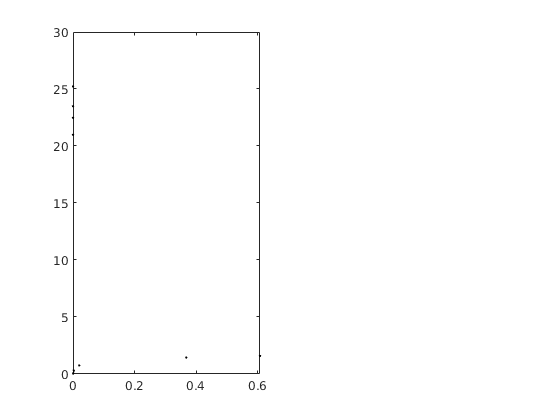

Error using hold
Too many output arguments.

set(0,'DefaultFigureWindowStyle','docked') %dock the figures..just a personal preference you don't need this.
x = 0.1; % initial actual state
x_N = 1; % Noise covariance in the system (i.e. process noise in the state update, here, we'll use a gaussian.)
x_R = 1; % Noise covariance in the measurement (i.e. the Quail creates complex illusions in its trail!)
T = 75; % duration the chase (i.e. number of iterations).
N = 10; % The number of particles the system generates. The larger this is, the better your approximation, but the more computation you need.

%initilize our initial, prior particle distribution as a gaussian around
%the true initial value

V = 2; %define the variance of the initial esimate
x_P = []; % define the vector of particles

% make the randomly generated particles from the initial prior gaussian distribution
for i = 1:N
    x_P(i) = x + sqrt(V) * randn;
end

%{
%show the distribution the particles around this initial value of x.
figure(1)
clf
subplot(121)
plot(1,x_P,'.k','markersize',5)
xlabel('time step')
ylabel('flight position')
subplot(122)
hist(x_P,100)
xlabel('flight position')
ylabel('count')
pause
%}

%the functions used by the Quail are:
% x = 0.5*x + 25*x/(1 + x^2) + 8*cos(1.2*(t-1)) + PROCESS NOISE --> sqrt(x_N)*randn
% z = x^2/20 + MEASUREMENT NOISE -->  sqrt(x_R)*randn;

%generate the observations from the randomly selected particles, based upon
%the given function
z_out = [x^2 / 20 + sqrt(x_R) * randn];  %the actual output vector for measurement values.
x_out = [x];  %the actual output vector for measurement values.
x_est = [x]; % time by time output of the particle filters estimate
x_est_out = [x_est]; % the vector of particle filter estimates.



for t = 1:T
    %from the previou time step, update the flight position, and observed
    %position (i.e. update the Quails position with the non linear function
    %and update from this position what the chasing ninja's see confounded
    %by the Quails illusions.
    x = 0.5*x + 25*x/(1 + x^2) + 8*cos(1.2*(t-1)) +  sqrt(x_N)*randn;
    z = x^2/20 + sqrt(x_R)*randn;
    %Here, we do the particle filter
    for i = 1:N
        %given the prior set of particle (i.e. randomly generated locations
        %the quail might be), run each of these particles through the state
        %update model to make a new set of transitioned particles.
        x_P_update(i) = 0.5*x_P(i) + 25*x_P(i)/(1 + x_P(i)^2) + 8*cos(1.2*(t-1)) + sqrt(x_N)*randn;
        %with these new updated particle locations, update the observations
        %for each of these particles.
        z_update(i) = x_P_update(i)^2/20;
        %Generate the weights for each of these particles.
        %The weights are based upon the probability of the given
        %observation for a particle, GIVEN the actual observation.
        %That is, if we observe a location z, and we know our observation error is
        %guassian with variance x_R, then the probability of seeing a given
        %z centered at that actual measurement is (from the equation of a
        %gaussian)
        P_w(i) = (1/sqrt(2*pi*x_R)) * exp(-(z - z_update(i))^2/(2*x_R));
    end
    
    % Normalize to form a probability distribution (i.e. sum to 1).
    P_w = P_w./sum(P_w);
    
    
    figure(1)
    clf
    subplot(121)
    plot(P_w,z_update,'.k','markersize',5)
    hold on
    plot(0,z,'.r','markersize',50)
    xlabel('weight magnitude')
    ylabel('observed values (z update)')    
    subplot(122)
    plot(P_w,x_P_update,'.k','markersize',5)
    hold on
    plot(0,x,'.r','markersize',50)
    xlabel('weight magnitude')
    ylabel('updated particle positions (x P update)')
    pause
    
    
    %plot the before and after
    figure(1)
    clf
    subplot(131)
    plot(0,x_P_update,'.k','markersize',5)
    title('raw estimates')
    xlabel('fixed time point')
    ylabel('estimated particles for flight position')
    subplot(132)
    plot(P_w,x_P_update,'.k','markersize',5)
    hold on
    plot(0,x,'.r','markersize',40)
    xlabel('weight magnitude')
    title('weighted estimates')
    

## Resampling: From this new distribution, now we randomly sample from it to generate our new estimate particles

    %what this code specifically does is randomly, uniformally, sample from
    %the cummulative distribution of the probability distribution
    %generated by the weighted vector P_w.  If you sample randomly over
    %this distribution, you will select values based upon there statistical
    %probability, and thus, on average, pick values with the higher weights
    %(i.e. high probability of being correct given the observation z).
    %store this new value to the new estimate which will go back into the
    %next iteration
    for i = 1 : N
        x_P(i) = x_P_update(find(rand <= cumsum(P_w),1));
    end
    
    %The final estimate is some metric of these final resampling, such as
    %the mean value or variance
    x_est = mean(x_P);
    
    %{
    %the after
    subplot(133)
    plot(0,x_P_update,'.k','markersize',5)
    hold on
    plot(0,x_P,'.r','markersize',5)
    plot(0,x_est,'.g','markersize',40)
    xlabel('fixed time point')
    title('weight based resampling')
    pause
    %}
    % Save data in arrays for later plotting
    x_out = [x_out x];
    z_out = [z_out z];
    x_est_out = [x_est_out x_est];
    
end

t = 0:T;
figure(1);
clf
plot(t, x_out, '.-b', t, x_est_out, '-.r','linewidth',3);
set(gca,'FontSize',12); set(gcf,'Color','White');
xlabel('time step'); ylabel('Quail flight position');
legend('True flight position', 'Particle filter estimate');